dentifikovane polynomy

pGain = [-7.74558355399971e-09 7.92523655765039e-06 -0.00291980737503381 0.463728547328537 -23.1386227555553];
pT = [1.10661505286941e-07 -5.48243874702451e-05 0.00740611980939077 -0.00882197108389277];
p = [1.27264127791514e-06,-0.000693202019254355,0.101241610731183,5.53942212609170,-881.974593934446];
pK = [6.06868337517324e-06,-0.00276839370282041,0.349669070323109,-3.90147463042572];
upb = 206;
upb_delta = 2;

PI regulator

b=0.707;
w0=10;

K =  polyval(pK, upb);
T = polyval(pT, upb);
Kp=(2*b*w0-1)/K;
Ki=w0^2*T/K;

Simulácia

out = sim('PI_sim.slx');



Vykreslenie

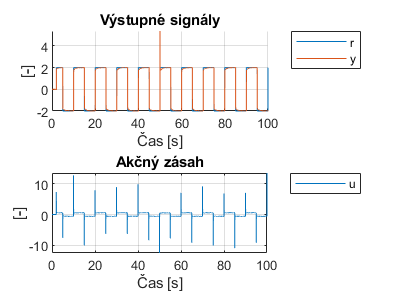

figure;
subplot(2,1,1);
hold on;
plot(out.tout,out.r.Data,'DisplayName','r');
plot(out.tout,out.y.Data,'DisplayName','y');
hold off;
xlabel('Čas [s]');ylabel('[-]');grid on; title('Výstupné signály');legend('Location',"bestoutside");



subplot(2,1,2);
plot(out.tout,out.u.Data,'DisplayName','u');
xlabel('Čas [s]');ylabel('[-]');grid on; title('Akčný zásah');legend('Location',"bestoutside");

Simulácia 2

upb=181;
K =  polyval(pK, upb);
T = polyval(pT, upb);
out = sim('PI_sim.slx');

Vykreslenie 2

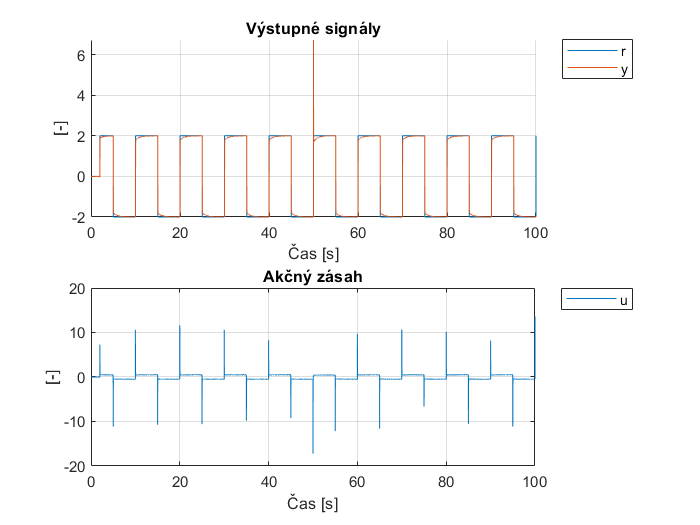

figure;
subplot(2,1,1);
hold on;
plot(out.tout,out.r.Data,'DisplayName','r');
plot(out.tout,out.y.Data,'DisplayName','y');
hold off;
xlabel('Čas [s]');ylabel('[-]');grid on; title('Výstupné signály');legend('Location',"bestoutside");



subplot(2,1,2);
plot(out.tout,out.u.Data,'DisplayName','u');
xlabel('Čas [s]');ylabel('[-]');grid on; title('Akčný zásah');legend('Location',"bestoutside");